# Segmenting Strawberries in a Field

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

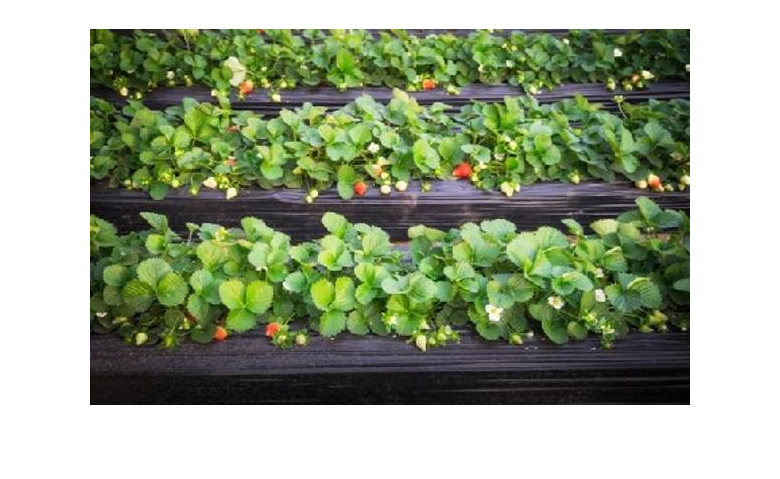

sb = imread("./images/strawberryPlant.jpg");
sbRows = imread("./images/strawberryRows.jpg");
imshow(sbRows)

## Task 1

In the last video, you learned how to use the Color Thresholder App to segment the strawberries in this image of a field. The function created by the app is saved as `createSBmask.m`.

`[``BW``,``maskedRGBImage``]` `=` `createSBmask``(``I``)``;`

You will use this function to programmatically segment images of strawberries.

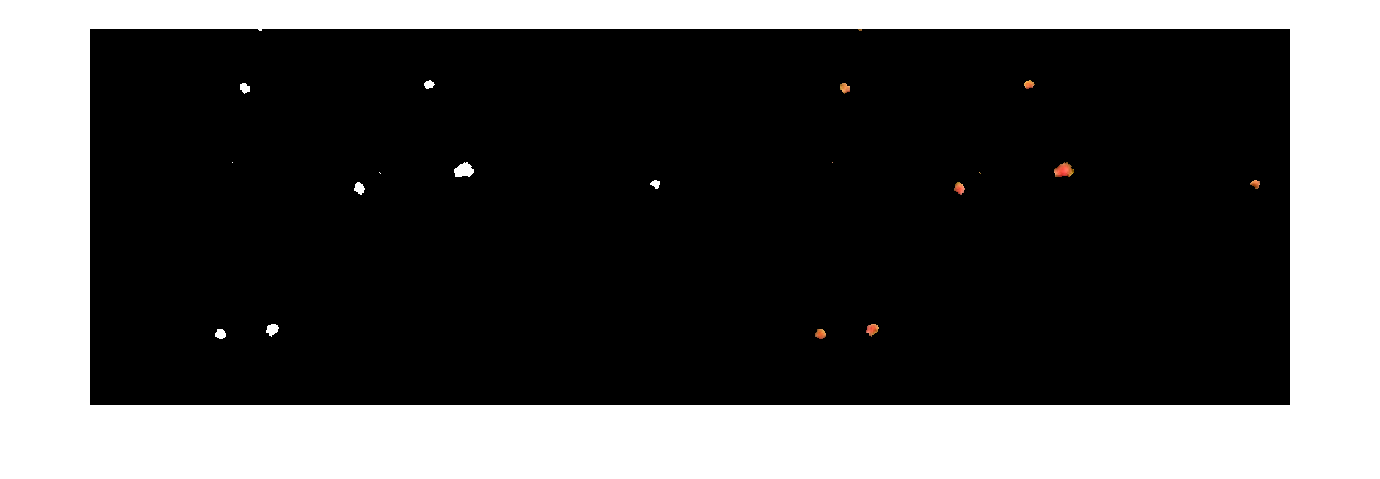

[BWsbRows, maskedRows] = createSBmask(sbRows);
imshowpair(BWsbRows, maskedRows, "montage")

## Task 2

You can apply `createSBmask` to any image.

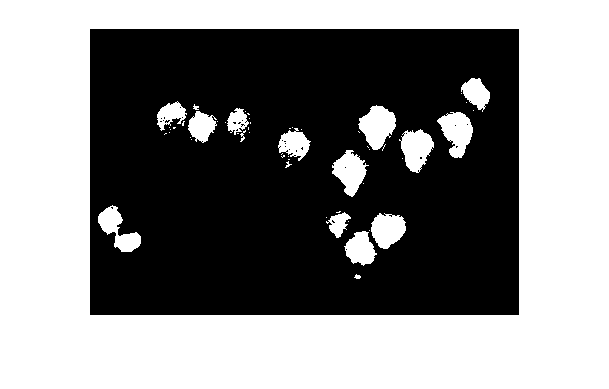

BWsb = createSBmask(sb);
imshow(BWsb)

## Task 3

You can use the `imoverlay` function to burn a mask onto an image.

`Ioverlay` `=` `imoverlay``(``I``,``BW``,``color``)``;`

Here, `Ioverlay` is an image that is a solid `color` everywhere `BW` is true and the same as `I` everywhere `BW` is false. So setting the color to `"m"` will make `I` magenta everywhere `BW` is true.

If you want to make the background a solid color, use `~``BW` as the second input.

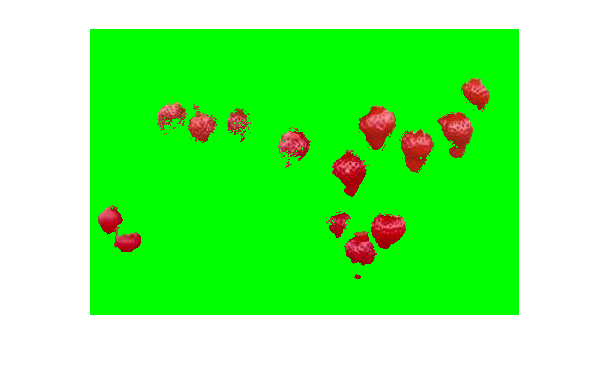

redSB = imoverlay(sb, ~BWsb, "g");
imshow(redSB)